clear; close all; clc

# Code to use Maximal Overlap Discrete Wavelet Transform (MODWT) to Analyze ECG Data

**Code authored by**: Shawhin Talebi

The University of Texas at Dallas

Mutli-scale Integrated Remote Sensing and Simulation (MINTS)

## Load Data

load('ECG_data.mat');

## Perform Wavelet Transform

Use the maximal overlap discrete wavelet transform (MODWT) to enhance the R peaks in the ECG waveform. The MODWT is an undecimated wavelet transform, which handles arbitrary sample sizes.

Perform MODWT for 6 different scales. The rows of wt give the wavelet (detail) coefficents for each scale. Here we are using Symlets wavelet with 4 vanishing moments

Other wavelet families can be used. use waveletfamilies('f') to view all

% define number of levels to use
numLevels = 6;

% perform maximal overlap discrete wavelet transform (MODWT)
wt = modwt(ECG, 'sym4', numLevels);

## Compare Coefficents for all MODWT Scales

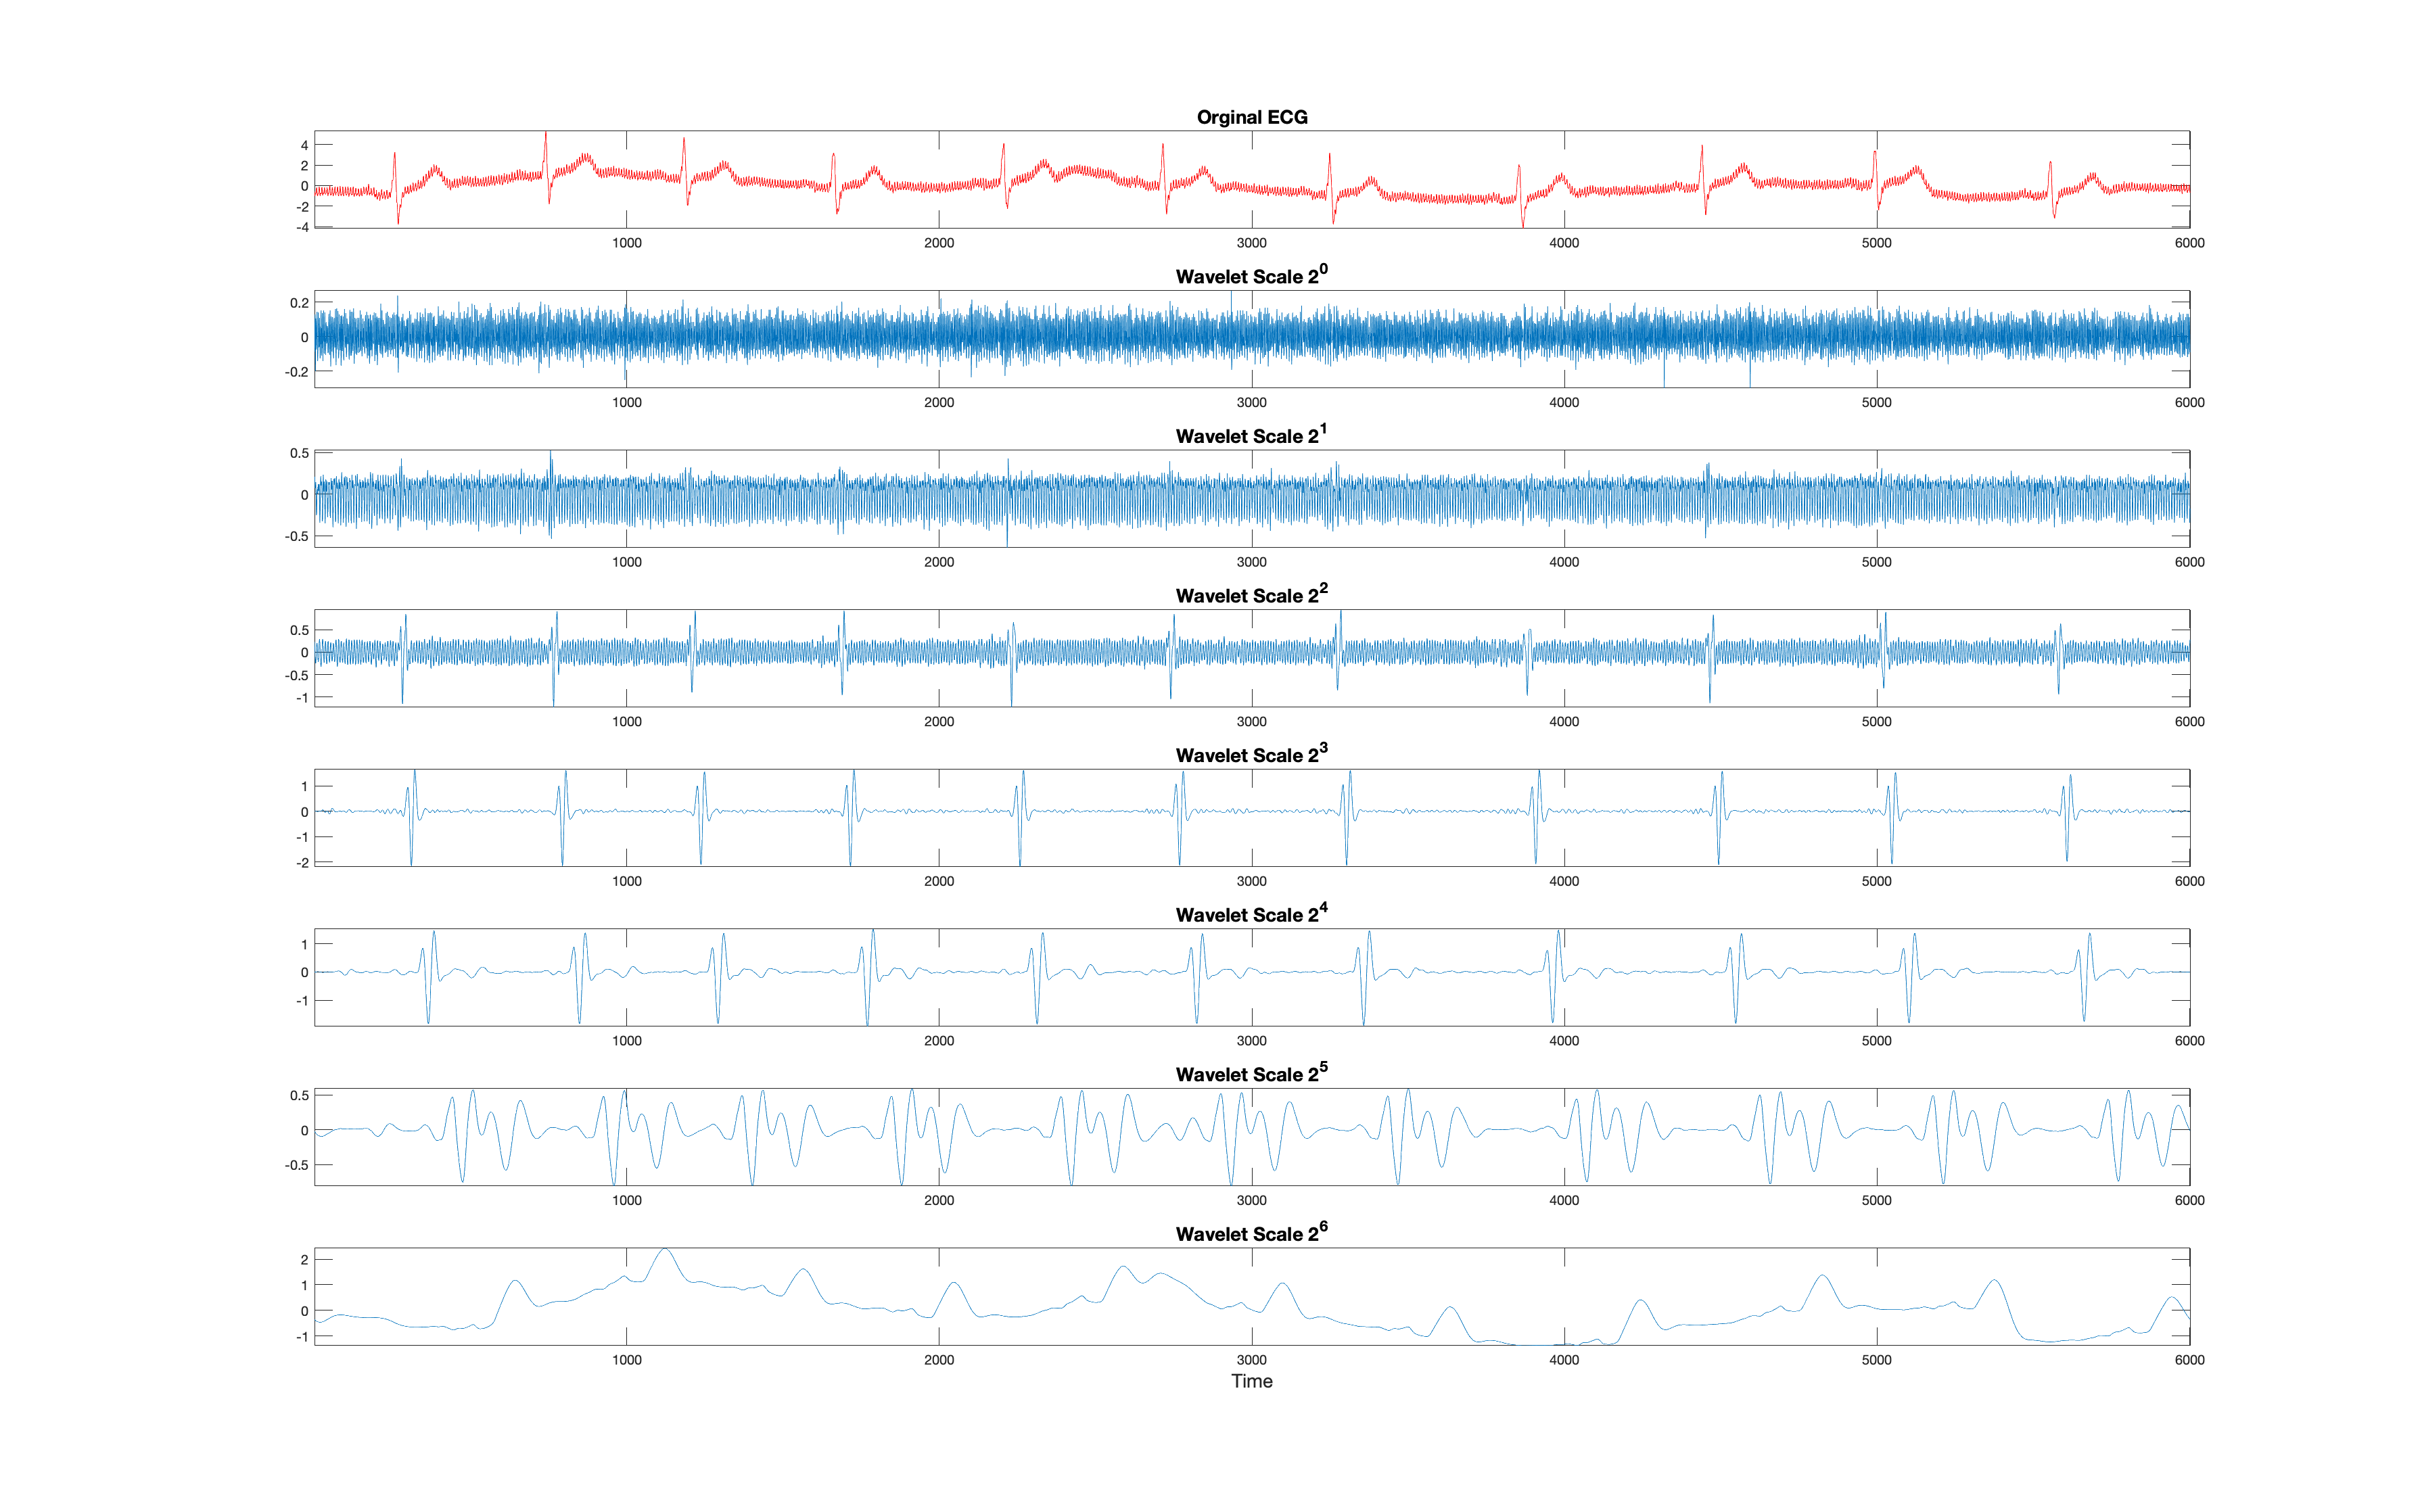

% get number of Wavelet Scales
[numScales, ~] = size(wt);

% create figure
fig = figure(1);
fig.Units = 'normalized';
fig.Position = [0 0 1 1];

% plot original signal
subplot(numScales+1,1,1)
plot(ECG, 'r-')
title('Orginal ECG', 'FontSize', 14)
axis tight

% plot wavelet scale coefficents
for i=2:numScales+1
    
    subplot(numScales+1,1,i)
    plot(wt(i-1,:))
    title(strcat('Wavelet Scale 2^', string(i-2)), 'FontSize', 14)
    axis tight
end

xlabel('Time', 'FontSize', 14)

% print figure to file
print('waveletTransform_signal_decomposition', '-dpng');

## Reconstruct Signal via Inverse MODWT

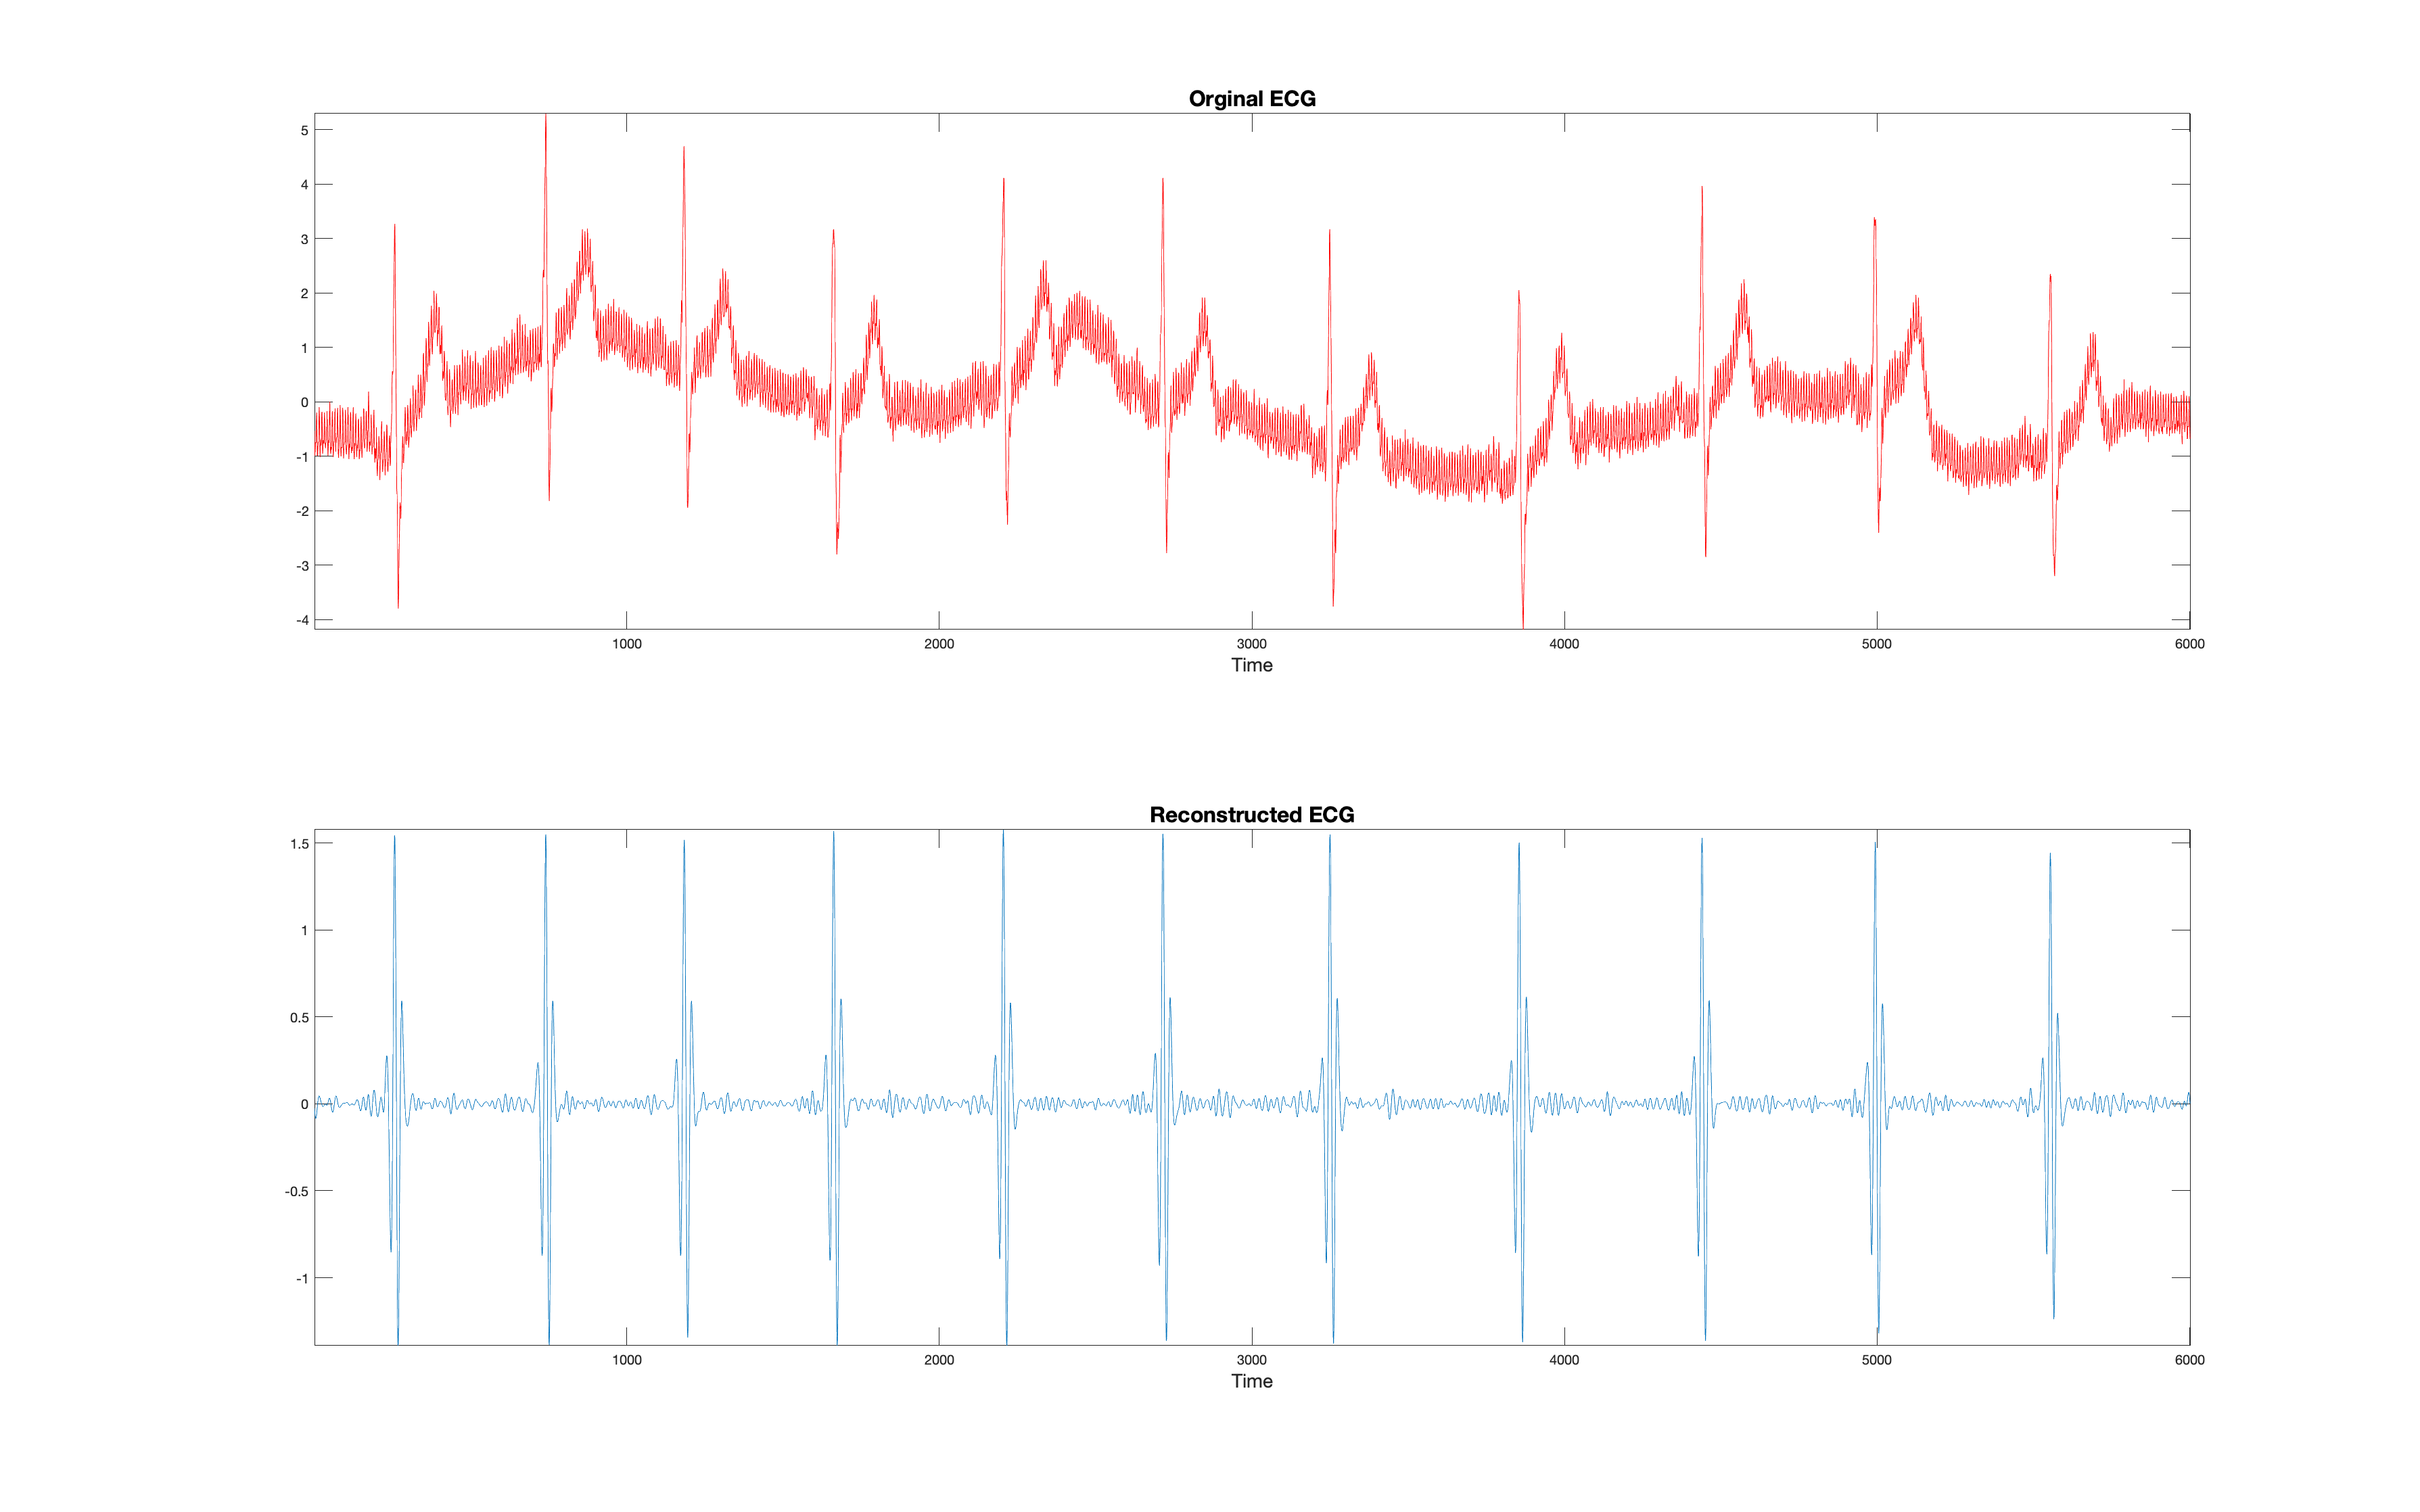

% create figure
fig = figure(2);
fig.Units = 'normalized';
fig.Position = [0 0 1 1];

% initialize an array to store the coefficents corresponding to scale 2^4
recwt = zeros(size(wt));

% store coefficents corresponding to scale 4 in array
recwt(4,:) = wt(4,:);

% reconstruct signal using only scale 4 with inverse transform
recECG = imodwt(recwt,'sym4');

% compare original signal and reconstructed
% plot original signal
subplot(2,1,1)
plot(ECG, 'r-')
title('Orginal ECG', 'FontSize', 16)
xlabel('Time', 'FontSize', 14)
axis tight
% plot reconstructed signal
subplot(2,1,2)
plot(recECG)
title('Reconstructed ECG', 'FontSize', 16)
xlabel('Time', 'FontSize', 14)
axis tight

% print figure to file
print('waveletTransform_reconstructed_signal', '-dpng');

## Find R Peaks Using Reconstructed Signal

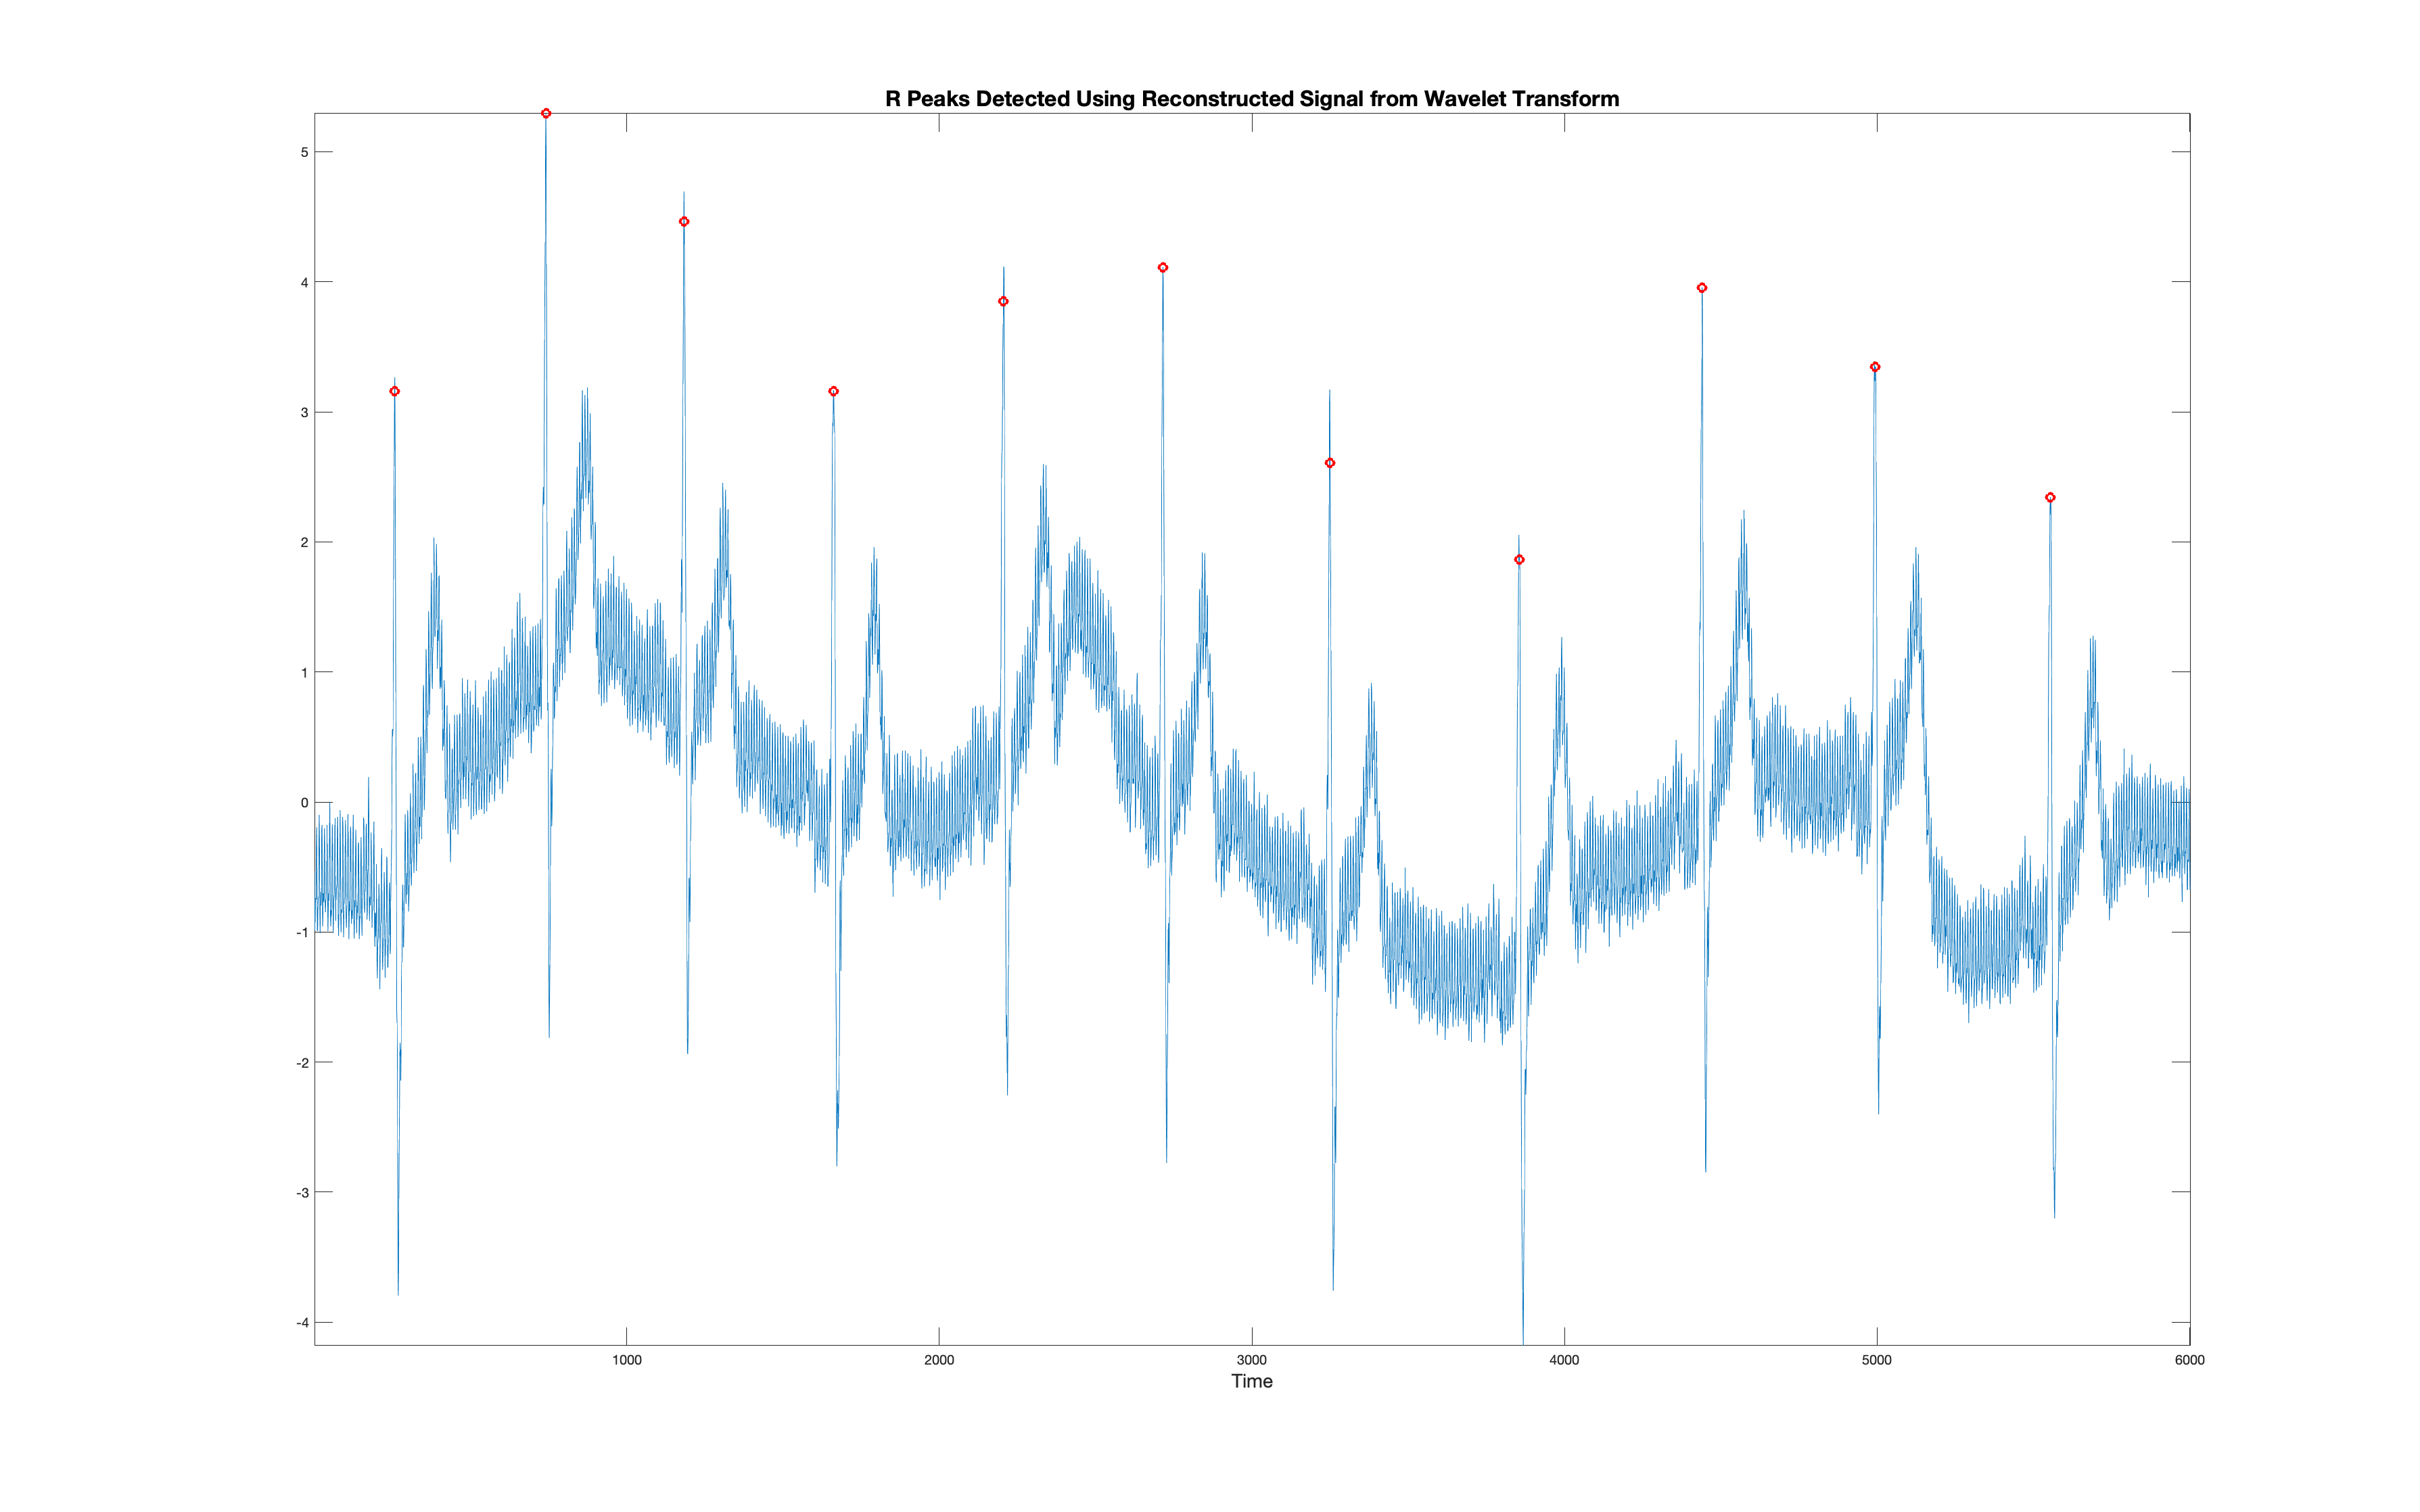

% define array of time indicies
t = 1:length(ECG);

% square reconstructed signal
recECG = abs(recECG).^2;
% find peaks in squared reconstructed signal
[qrspeaks,locs] = findpeaks(recECG, t, 'MinPeakHeight', 0.35,'MinPeakDistance',100);

% create figure
fig = figure(3);
fig.Units = 'normalized';
fig.Position = [0 0 1 1];

% plot signal with detected r peaks using reconstructed signal from DWT
plot(t,ECG)
hold on
plot(locs,ECG(locs),'ro', 'LineWidth', 2)
xlabel('Time', 'FontSize', 14)
title('R Peaks Detected Using Reconstructed Signal from Wavelet Transform', ...
    'FontSize', 16)
axis tight
print('waveletTransform_rpeak_annotation', '-dpng');